clear
clc
close all

#### Un sistema de referencia OXYZ se gira 90º con respecto a su eje Z y posteriormente otros -90º con respecto a sus eje X’, seguido un giro final de 90º  con respecto a Y’’ (rotaciones intrínsecas o relativas). 

- Construye las matrices básicas de rotación con respecto a cada eje, y calcula la matriz final de rotación R que representa ambos giros. 

M_1=rotz(90)

M_1 =      0    -1     0
     1     0     0
     0     0     1


M_2=rotx(-90)

M_2 =      1     0     0
     0     0     1
     0    -1     0


M_3=roty(90)

M_3 =      0     0     1
     0     1     0
    -1     0     0



matrixRotacion=M_1*M_2*M_3

matrixRotacion =      1     0     0
     0     0     1
     0    -1     0


- Representa gráficamente la orientación del sistema final girado basándote en las columnas de la matriz de rotación. 

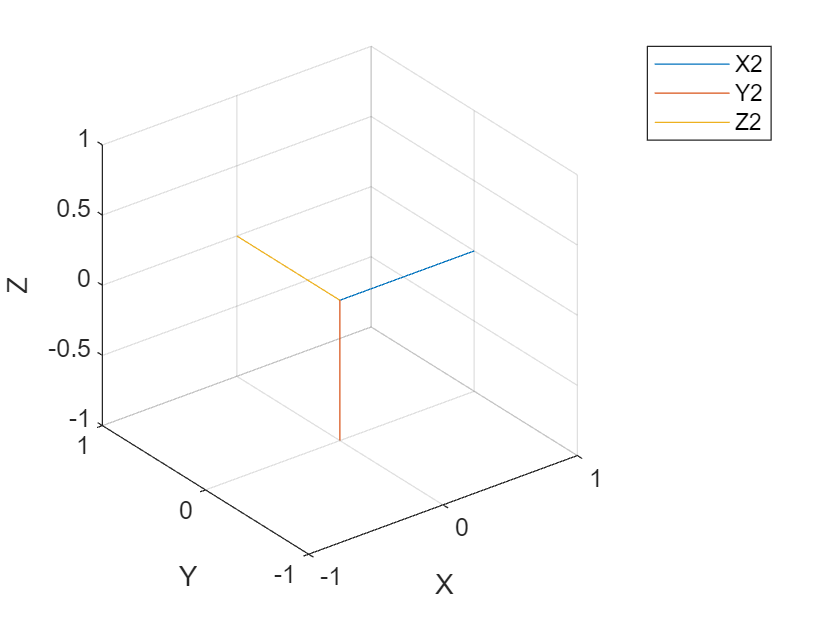

ejeX=matrixRotacion(:,1);
ejeY=matrixRotacion(:,2);
ejeZ=matrixRotacion(:,3);

figure();
plot3([0, ejeX(1)],[0, ejeX(2)],[0, ejeX(3)]);
hold on
plot3([0, ejeY(1)],[0, ejeY(2)],[0, ejeY(3)]);
plot3([0, ejeZ(1)],[0, ejeZ(2)],[0, ejeZ(3)]);
grid on
xlabel('X')
ylabel('Y')
zlabel('Z')
xlim([-1 1]);
ylim([-1 1]);
zlim([-1 1]);

legend('X2', 'Y2', 'Z2')

- ¿Hay algún eje que permanezca en la misma orientación?

El eje X permanece en la misma posición

- Comprueba el resultado mediante la aplicación *Rotation Viewer *para MATLAB.

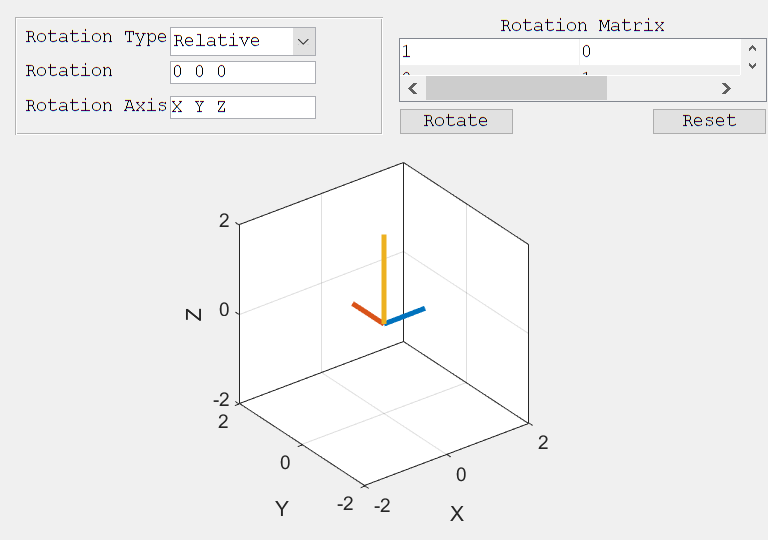

RotationViewer;